# Labo1A - Introduction aux signaux et systèmes numériques

clc; clear; close all;

## Numérisation des signaux analogiques

Lorsqu’on analyse et/ou traite signaux par programmation (Matlab ou autres), ces signaux sont par définition numériques et discrets. Au sens strict, on ne peut donc plus parler de signaux analogiques. Cependant, on se permet de le faire si l’incrément temporel utilisé pour les décrire est beaucoup plus petit que le temps caractéristique minimum du signal. Dans tout ce qui suit, il est donc extrêmement important de bien distinguer au niveau des variables entre les signaux analogiques numérisés xt (équivalent de x(t)) et les signaux échantillonnés xn (équivalent de x[k]) qui sont tous deux numériques.

Dans le premier cas, on choisira un nombre élevé de points de manière à avoir un incrément temporel dt très petit alors que dans le deuxième cas, l’incrément temporel Te sera fixé par la fréquence d’échantillonnage qui doit respecter le théorème de Shannon (fe > 2Fmax); généralement, le nombre de points sera beaucoup moins élevé que dans le premier cas. Une illustration en est donnée dans la figure  ci-dessous.

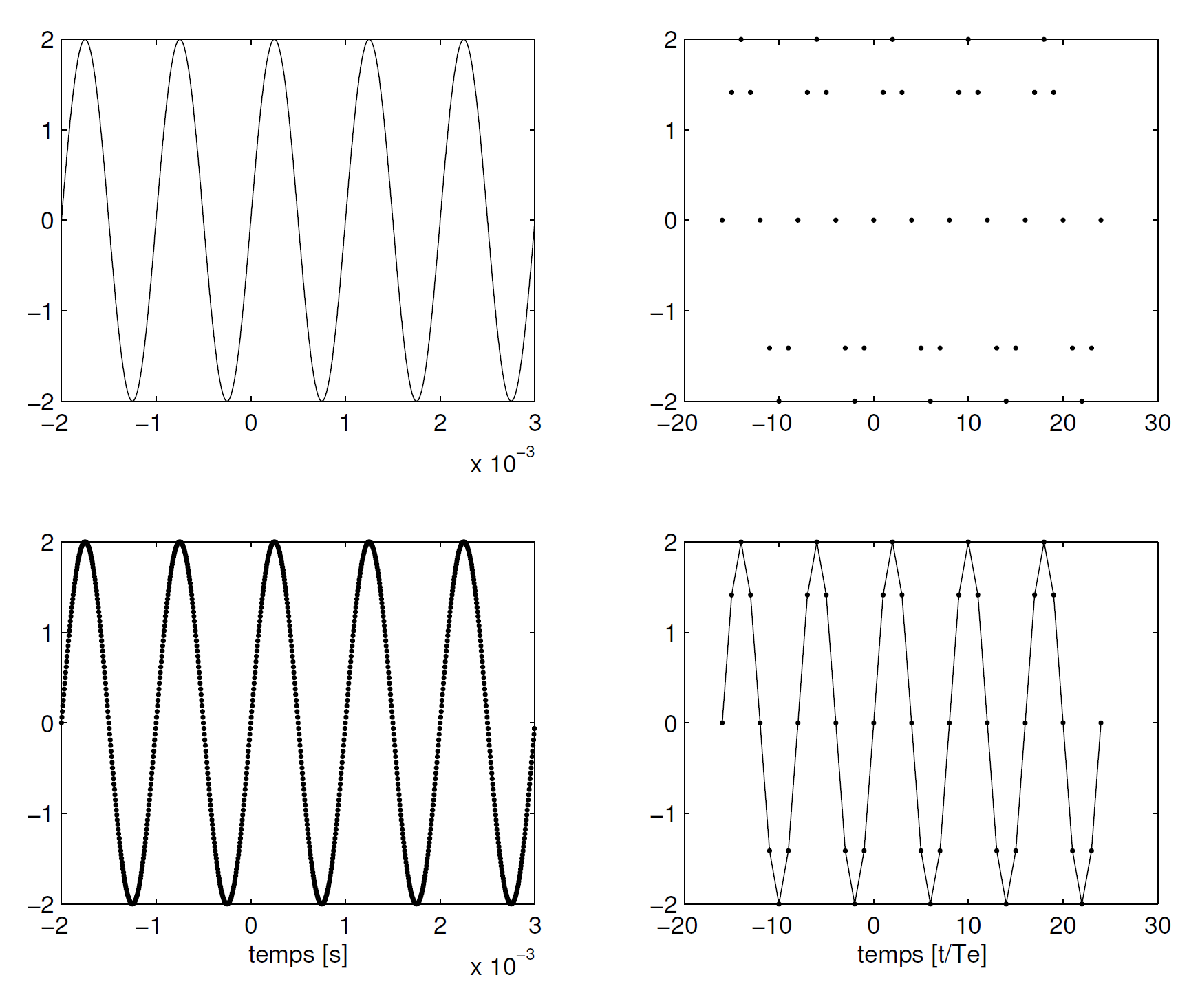

## Echantillonage des signaux analogiques

### Signal sinusoidal

- Construisez un signal x(t) avec : période T0 = 1 ms, durée tmax = 20 ms, incrément temporel de 20 us.

- Tracez ce signal (plot(tt,xt)) dans une fenêtre subplot (5,1,1)

- Échantillonnez ce signal avec les fréquences d’échantillonnage fe valant 4kHz, 2kHz, 1.1kHz, 0.9kHz

- Tracez (plot(tn,xn)) les signaux x[n] dans les fenêtres (5,1,k).

- Observez et concluez.

% Votre code




### Signal audio

Dans cette section, vous allez créer un son pur échantillonné à 8 kHz durant 1 seconde. À l’aide de la carte-son, vous écouterez plusieurs sons dont les 9 fréquences sont comprises entre 800 Hz et 7200 Hz. Pour ce faire, créez une boucle for k1 = 1:9 dans laquelle vous :

1. générez les signaux sinusoïdaux de fréquence* f0 = k1*800* et d’amplitude 1 ;

2. tracez les graphes correspondants avec *subplot(3,3,k1); plot(tn(1:80),xn(1:80)); ylabel(num2str(f0));*

3. écoutez le signal avec *soundsc(xn,fe);* *pause(2);*

% Votre code


## Analyse de signaux périodiques

Le but de ce travail pratique est d’apprendre à générer et analyser des signaux dans les domaines temporels et fréquentiels. Pour ce faire, vous créerez des signaux périodiques tels que les suites d’impulsions rectangulaires (SIR), triangulaires (SIT), exponentielles (SIE) et oscillantes amorties (SINAM) pour les analyser ensuite. Voir figure 2 pour les paramètres de chaque signal.

Pour ce faire commencez par lire les fonctions *sir.m, sit.m, sie.m, sinam.m* génératrices de quelques signaux utiles et observez à quel point il est simple de créer des signaux périodiques où, sauf pour la SIT, deux lignes de code suffisent. Puis, dans la fenêtre de commandes Matlab, tapez *help sir.m* ou autres pour voir comment on utilise ces fonctions.

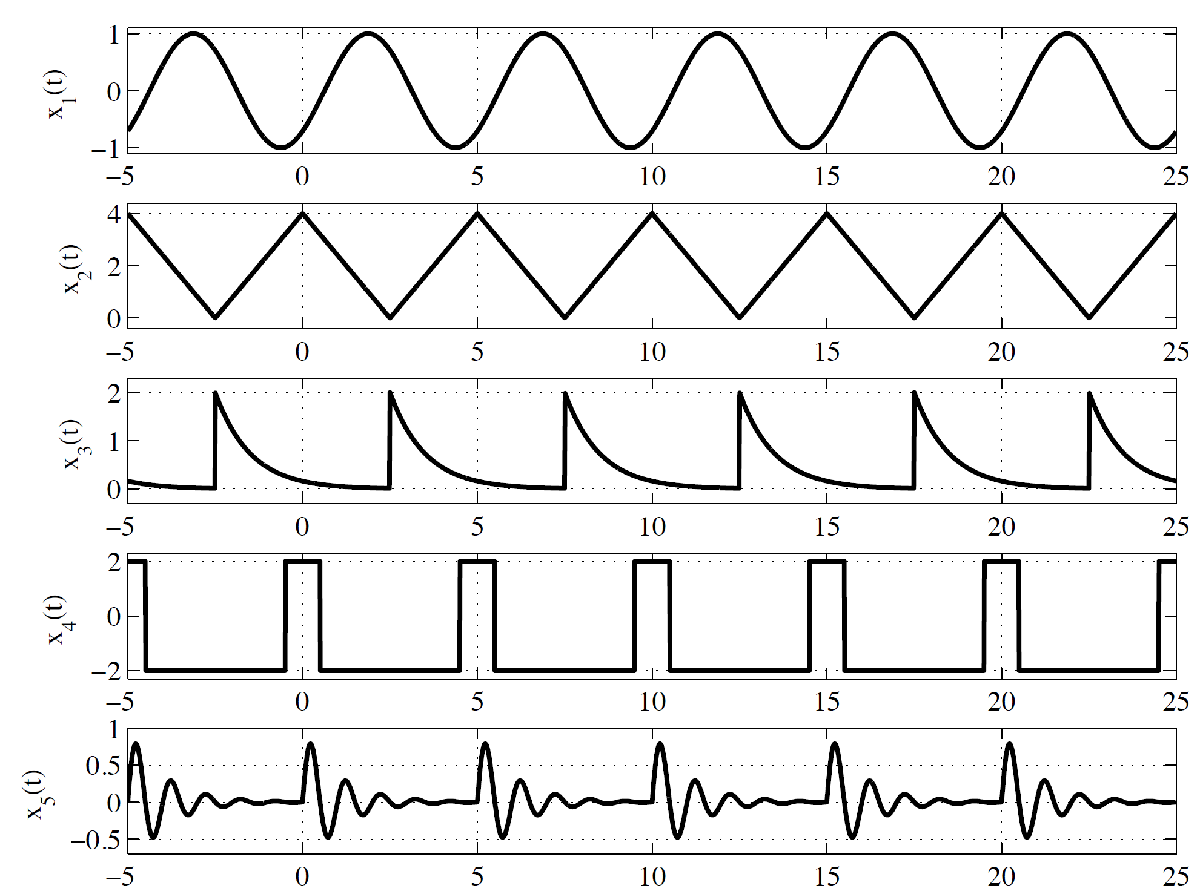

### Analyse temporelle

#### Création de quelques signaux

Écrivez un fichier *signaux_a.m* dans lequel vous calculerez et tracerez les signaux de la figure 2.

- Générez un vecteur temps constitué de N = 1000 valeurs comprises entre tmin et tmax.

- Pour chacun des signaux, définissez les paramètres tdec, T0, rc, tau , Tp ainsi que l’amplitude A et le décalage en ordonnée.

- Calculez et tracez les cinq signaux.

- Modifiez les valeurs des paramètres ; est-ce que tout se passe bien ? est-il raisonnable de prendre des valeurs faibles pour N ?

[x1,x2,x3,x4,x5] = signaux_a(); % Vous devez compléter la fonction

#### Valeurs moyennes, puissance

Pour mémoire, on rappelle que la puissance d’un signal peut être calculée soit dans le domaine temporel, soit dans le domaine fréquentiel (composante DC et composante AC).


$$P_x =\frac{1}{T}\int_{\textrm{to}}^{\textrm{to}+T} \left|x\left(t\right){\left|\right.}^2 \textrm{dt}\right.$$


La puissance totale d’un signal est égale à la somme des puissances DC et AC


$$P_x =P_{\textrm{dc}} +P_{\textrm{ac}} =X_{\textrm{dc}}^2 +X_{\textrm{ac}}^2$$


On en déduit alors que la puissance et la valeur efficace de la composante alternative valent


$$\begin{array}{l}
P_{\textrm{ac}} =P_x -X_{\textrm{dc}}^2 \\
X_{\textrm{ac}} =\sqrt{P_{\textrm{ac}} }
\end{array}$$


Comme les signaux que l’on traite avec Matlab sont des grandeurs analogiques numérisées, il est important de définir comment on calcule les valeurs associées aux signaux analogiques *x(t)* ou numériques *x[n] *:

- la composante continue ou valeur moyenne du signal


$$\begin{array}{l}
X_{\textrm{dc}} =\frac{1}{T}\int_{t_0 }^{t_0 +T} x\left(t\right)\textrm{dt}\\
X_{\textrm{dc}} =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack 
\end{array}$$


- la puissance normalisée du signal


$$\begin{array}{l}
P_x =\frac{1}{T}\int_{t_0 }^{t_0 +T} \left|x\left(t\right){\left|\right.}^2 \textrm{dt}\right.\\
P_x =\frac{1}{N}\;\sum_{n=0}^{N-1} {\left|x\left\lbrack n\right\rbrack \right|}^2 
\end{array}$$


Afin d’obtenir les paramètres caractéristiques de vos signaux, écrivez une fonction fournissant ces valeurs :

[Xdc, Xac, Px] = ParamSignal(x1); % Vous devez compléter la fonction

Quatre lignes de codes suffisent si vous employez les deux fonctions élémentaires, mais très utiles, que sont *sum()* et *length()*.

#### Analyse des résultats

Pour chacun des signaux ci-dessus :

- calculez avec Matlab les valeurs théoriques des paramètres Xdc, Xac, Px ; Les valeurs théoriques sont à calculer avec les signaux continus, en utilisant l’intégrale (voir Annexe ci-dessous)

- utilisez votre fonction ParamSignal.m pour calculez les valeurs réelles ;

- comparez ces résultats aux valeurs théoriques et expliquez les différences éventuelles.

% votre code

Unrecognized function or variable 'xn'.

Error in ParamSignal (line 16)
Px = sum(xn.^2)/length(xt);

## Annexe : Formules théoriques pour le calcul de la puissance

- Pour le signal SIR la puissance est donné par la formule 5.34 du support de cours.

- Pour le signal triangulaire SIT la puissance est donné par la formule 5.36 du support de cours.

- Pour le signal exponentiel périodique SIE la puissance est donné par la formule 5.38 du support de cours.